## Rete Anticipatrice

Definizione del **numeratore** e del **denominatore** della **FdT P(s)**.

num = 1;
den = conv([1 0],[1 -1]);

P_s = tf(num,den)


P_s =
 
     1
  -------
  s^2 - s
 
Continuous-time transfer function.
Model Properties


Determinare i valori di **K** e **Tau** affinchè:

- La **Pulsazione di attraversamento F(s)=G(s)P(s) **sia la stessa di** P(s)**.

- Il sistema sia asintoticamente stabile e con **Margine di fase **maggiore possibile**.**

- Verificare la stabilità asintotica con** Nyquist.**

Calcolo del **Margine di Guadagno** e** di Fase **della funzione **P(s)**.

- Dal diagramma si nota che il **margine di fase** è negativo, allora il sistema può essere instabile.

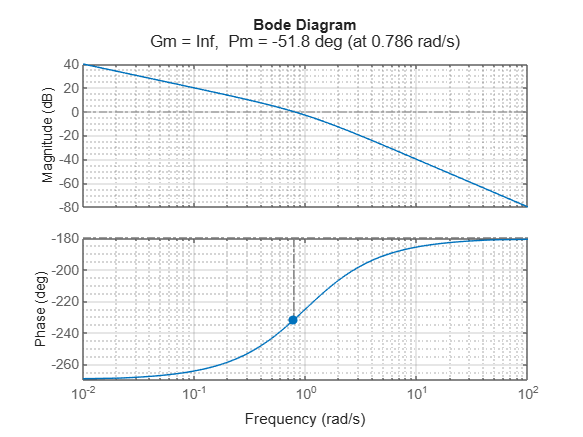

margin(P_s)
grid on
grid minor

Calcolo delle **radici **del** polinomio caratteristico**.

- Polinomio caratteristico: D(s) + N(s) (Denominatore + Numeratore).

- Si nota che le radici hanno parte reale positiva e quindi sistema potenzialmente instabile.

pol_car =  [1 -1 1]; % polinomio caratteristico: s^2 - s + 1
sys_roots = roots(pol_car)

sys_roots =    0.5000 + 0.8660i
   0.5000 - 0.8660i


Calcolo di **K **e **Tau **per la** rete anticipatrice G(s)**.

- Analizzando il diagramma universale della rete anticipatrice della FASE (vedi slide) per 𝑚 = 10 (parametro fissato da specifiche), si nota che il picco di incremento di fase si ottiene per un valore di ascissa 𝜔𝜏 ≅ 3.2 (requisito, incrementare il più possibile il margine di fase).

- Il valore di 𝜏 richiesto, lo si calcola imponendo il picco avvenga nella pulsazione di attraversamento 𝜔𝑡=0.786𝑟𝑎𝑑/𝑠 (rimane, quindi, invariata). Con 𝜔𝜏 ≅ 3.2 e 𝜔𝑡 = 0.786 --> 𝜏 = 3.2/0.786 = 4.071[s].

- Dal diagramma universale della rete anticipatrice del **Modulo** (slide) si nota che per 𝑚 = 10 si ha un aumento di circa 10 [dB] del modulo che quindi fa spostare a destra (aumentare) la 𝜔𝑡. Allora di calcola un valore di K [dB] che riduca il modulo di 10 [dB] --> 20log10(K) = -10 --> K = 10^(-10/20) ≅ 0.3162.

K = 0.3162;
tau = 4.071

tau = 4.0710

m = 10;

num = K*[tau 1];
den = [tau/m 1]

den =     0.4071    1.0000



G_s = tf(num,den);

**Funzione ad anello aperto complessiva F(s).**

- **F(s) = G(s)P(s).**

F_s = G_s*P_s;

hold on
margin(F_s)
grid on
grid minor

- Dal diagramma si nota che c'è stato un notevole aumento di del margine di fase, ma la pulsazione di attraversamento 𝜔𝑡 è leggermente diversa da 0.786 [rad/s] dovuto al calcolo non preciso di K (diagramma universale). Iterativamente di calcola un valore ottimale per K_r = 0.313

K_r = 0.313;
tau = 4.071

tau = 4.0710

m = 10;

num = K_r*[tau 1];
den = [tau/m 1]

den =     0.4071    1.0000


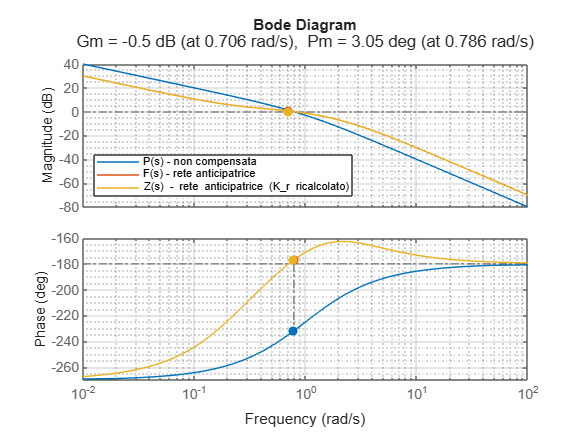


K_s = tf(num,den);

Z_s = K_s*P_s;

hold on
margin(Z_s)
grid on
grid minor
hold off
legend("P(s) - non compensata","F(s) - rete anticipatrice", "Z(s) - rete anticipatrice (K_r ricalcolato)");
legend("Location","southwest");

Verifica della stabilità del sistema.

% Radici della FdT Z(s).
den_z_s = [0.4071 0.5929 -1 0]; % Denominatore.
z_s_roots = roots(den_Z_s) % Radici del denominatore.

z_s_roots =          0
   -2.4564
    1.0000


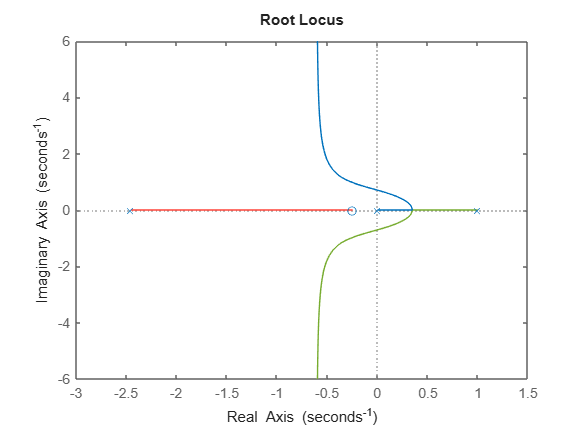


rlocus(Z_s) % Luogo delle radici.